%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

PROJETO DE FILTRO IIR - PARAMETRO 5

Disciplina: Processamento Digital de Sinais

### DISCENTES: 

- HANNA VITÓRIA DE OLIVEIRA SILVA

- LUCILA GABRIELA GOMES COSTA

- MARIA LUIZA MELO SILVA

Projeto baseado no enunciado (Parametro 5):

 f1 = 5.5 kHz|  f2 = 5.8 kHz

delta2 = 0.000316  => Ar ~ -70 dB

clear; clc; close all;

%% 1) Parametros gerais

Fs    = 44100;   % Taxa de amostragem (Hz)
dur   = 5;       % Duracao do audio (s)
nBits = 16;      % Resolucao do audio em bits
nChan = 1;       % Mono

% Parametros do ruido - CONJUNTO 5
f1 = 5500;         % Hz
f2 = 5800;         % Hz
delta2 = 0.000316; % Nivel maximo na banda de rejeicao (linear)

% Atenuacao minima no rejeita-faixa (em dB)
Ar = 20*log10(delta2);   % aproximadamente -70 dB
Rs = abs(Ar);            % parametro positivo p/ cheb2ord / cheby2

% Ripple maximo na banda de passagem (dB)
Rp = 1;                  % tipicamente 0.5 ~ 1 dB

fprintf('Atenuacao minima desejada no stopband: %.2f dB\n', Ar);

Atenuacao minima desejada no stopband: -70.01 dB



%% 2) Captura do sinal de voz v[n]

% % 
% % disp('>>> GRAVACAO DE VOZ (5 segundos) <<<');
% % recObj = audiorecorder(Fs, nBits, nChan);
% % 
% % disp('Fale agora...');
% % recordblocking(recObj, dur);
% % disp('Gravacao encerrada.');
% % v = getaudiodata(recObj);

arquivo_mp4 = 'Audio_Hanna.mp4'; 

% Importar o áudio do MP4
[audio_original, fs_original] = audioread(arquivo_mp4);

% Converter para vetor linha
v_importado = audio_original(:)';

% Reamostrar 
if fs_original ~= Fs
    fprintf('Reamostrando para %d Hz...\n', fs_original, Fs);
    v = resample(v_importado, Fs, fs_original);
else
    v = v_importado;
end

Reamostrando para 48000 Hz...
Reamostrando para 44100 Hz...


v = v(:);                 % garante vetor coluna
N = length(v);
t = (0:N-1).'/Fs;         % eixo de tempo em segundos (coluna)

% Salva a voz original
audiowrite('voz_original_param5.wav', v, Fs);

%% 3) Geracao do ruido r[n] e sinal corrompido z[n]

a1 = 0.5;   % amplitudes do ruido (ajustar conforme desejado)
a2 = 0.5;

r = a1*cos(2*pi*f1*t) + a2*cos(2*pi*f2*t);   % ruido senoidal composto
z = v + r;                                   % sinal de voz corrompido

% Salva a voz com ruido
audiowrite('voz_ruidosa_param5.wav', z, Fs);


%% 4) Projeto do filtro IIR rejeita-faixa (bandstop)

% Escolha de frequencias de passagem e rejeicao:
% Queremos rejeitar 5.5 kHz a 5.8 kHz.
% Definimos passband um pouco antes e depois para criar a banda de transicao.

fp1 = 5300;    % Hz - limite superior da 1a banda de passagem
fp2 = 6000;    % Hz - limite inferior da 2a banda de passagem
fs1 = 5500;    % Hz - inicio da banda de rejeicao
fs2 = 5800;    % Hz - fim da banda de rejeicao

% Normalizacao pela frequencia de Nyquist (Fs/2)
Wp = [fp1 fp2]/(Fs/2);   % frequencias de passagem normalizadas
Ws = [fs1 fs2]/(Fs/2);   % frequencias de rejeicao normalizadas

% Determinacao da ordem minima do filtro Chebyshev II
[Ncheb, Wn] = cheb2ord(Wp, Ws, Rp, Rs);

fprintf('Ordem do filtro Chebyshev Tipo II projetado: N = %d\n', Ncheb);

Ordem do filtro Chebyshev Tipo II projetado: N = 7


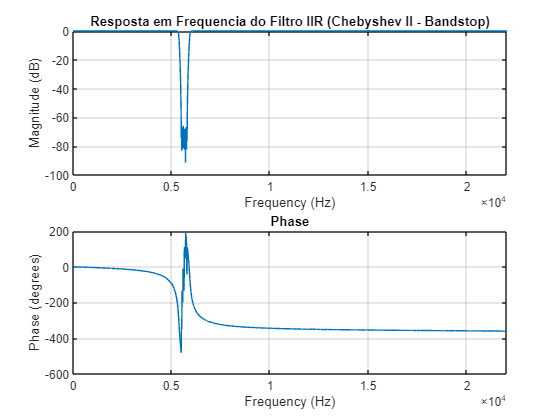


% Projeto do filtro Chebyshev II do tipo rejeita-faixa (bandstop)
[b, a] = cheby2(Ncheb, Rs, Wn, 'stop');

%% 5) Resposta em frequencia do filtro projetado

figure;
freqz(b, a, 4096, Fs);
title('Resposta em Frequencia do Filtro IIR (Chebyshev II - Bandstop)');
grid on;

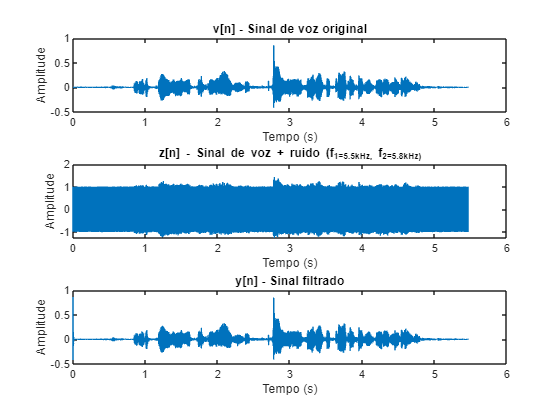


%% 6) Filtragem do sinal ruidoso

y = filter(b, a, z);

% Salva a voz filtrada
audiowrite('voz_filtrada_param5.wav', y, Fs);

%% 7) Analise no dominio do tempo

figure;
subplot(3,1,1);
plot(t, v);
xlabel('Tempo (s)'); ylabel('Amplitude');
title('v[n] - Sinal de voz original');

subplot(3,1,2);
plot(t, z);
xlabel('Tempo (s)'); ylabel('Amplitude');
title('z[n] - Sinal de voz + ruido (f_1=5.5kHz, f_2=5.8kHz)');

subplot(3,1,3);
plot(t, y);
xlabel('Tempo (s)'); ylabel('Amplitude');
title('y[n] - Sinal filtrado');

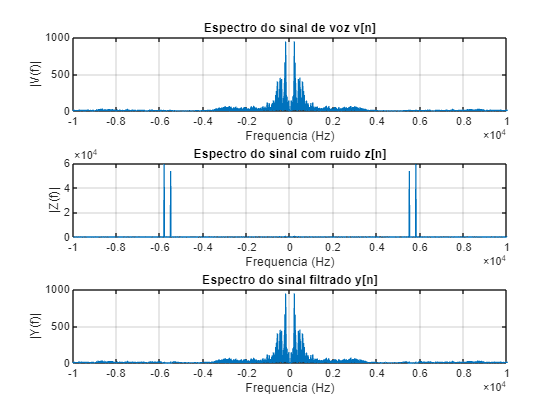


%% 8) Analise no dominio da frequencia (FFT)

V = fftshift(fft(v));
Z = fftshift(fft(z));
Y = fftshift(fft(y));

f = linspace(-Fs/2, Fs/2, N);    % eixo de frequencia em Hz

figure;
subplot(3,1,1);
plot(f, abs(V));
xlabel('Frequencia (Hz)'); ylabel('|V(f)|');
title('Espectro do sinal de voz v[n]');
xlim([-10000 10000]); grid on;

subplot(3,1,2);
plot(f, abs(Z));
xlabel('Frequencia (Hz)'); ylabel('|Z(f)|');
title('Espectro do sinal com ruido z[n]');
xlim([-10000 10000]); grid on;

subplot(3,1,3);
plot(f, abs(Y));
xlabel('Frequencia (Hz)'); ylabel('|Y(f)|');
title('Espectro do sinal filtrado y[n]');
xlim([-10000 10000]); grid on;